# `TernaryChart`** Examples**

**Overview**

The `TernaryChart` manages a barycentric plot of three variables $A$, $B$ and $C$ that sum to a constant. The chart provides a smooth, interpolated surface for the observed data $Z$. The chart data comprises a table of numeric data containing the three input variables $A$, $B$, $C$ together with the response (output) variable $Z$. For each data point $(A_i, B_i, C_i, Z_i)$ we have $A_i + B_i + C_i=1$. The chart is equipped with a control panel and contains interactive information on the data composition at each specific point via data tips.

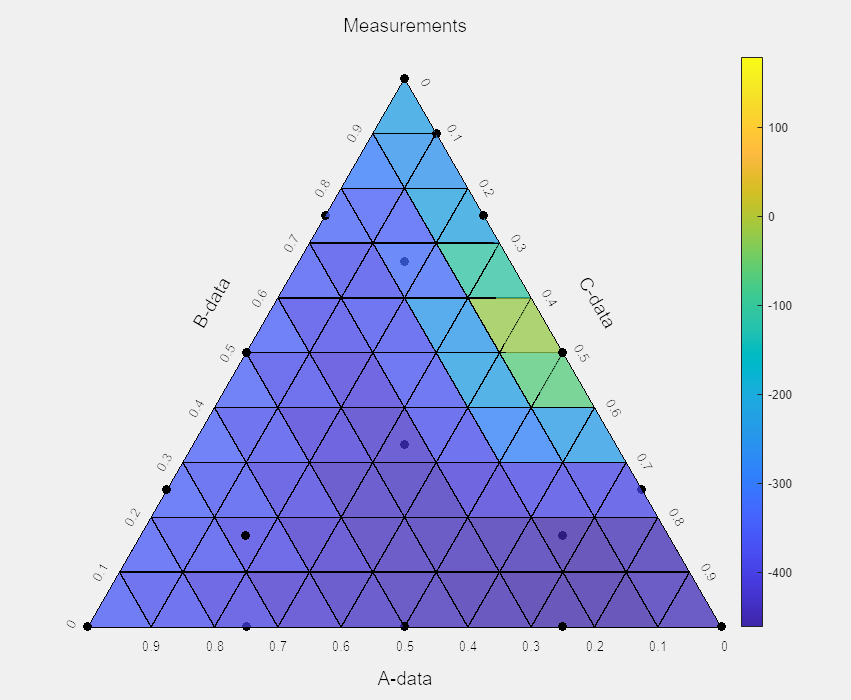

**Resources**

[Open](matlab: edit( fullfile( catalogRoot(), "+example", "Ternary.mlx" ) )) this Live Script to run and interact with the examples shown below.

[View](matlab: edit( fullfile( catalogRoot(), "+chart", "Ternary.m" ) )) the source code for the `Ternary` chart.

Documentation for:

- [`patch`](matlab: doc( "patch" )): create a surface plot with variable goemetric shapes.

- [`line`](matlab: doc( "line" )): create a line with variable properties (used for the discrete points).

## Load sample data for the chart.

This data set comprises three chemicals (methanol, acetone and chloroform) together with the bubble point of the ternary mixture at a fixed pressure.

load( fullfile( chartsDocRoot(), "data", "Chemicals.mat" ) )
disp( T )

      A        B        C        Z  
    _____    _____    _____    _____

        1        0        0     64.5
        0        1        0       56
        0        0        1     61.1
      0.5      0.5        0    56.27
      0.5        0      0.5    54.17
        0      0.5      0.5    63.64
    0.333    0.333    0.333    57.43
     0.75     0.25        0    58.67
     0.25     0.75        0    55.37
     0.75        0     0.25    56.72
     0.25        0     0.75    53.94
        0     0.75     0.25    60.15
        0     0.25     0.75    64.17
    0.667    0.167    0.167    57.92
    0.167    0.667    0.167    57.29
    0.167    0.167    0.667    56.91
    0.439    0.332    0.229    57.32



## Create a figure for the chart.

f = exampleFigure( "Name", "TernaryChart Example" );

## Create the chart.

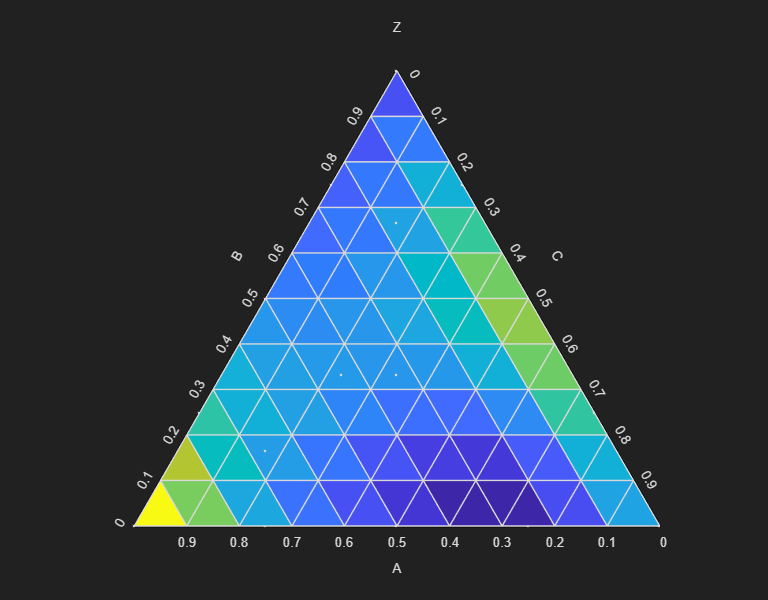

TC = TernaryChart( "Parent", f, ...
    "Data", T );

## Annotate the chart.

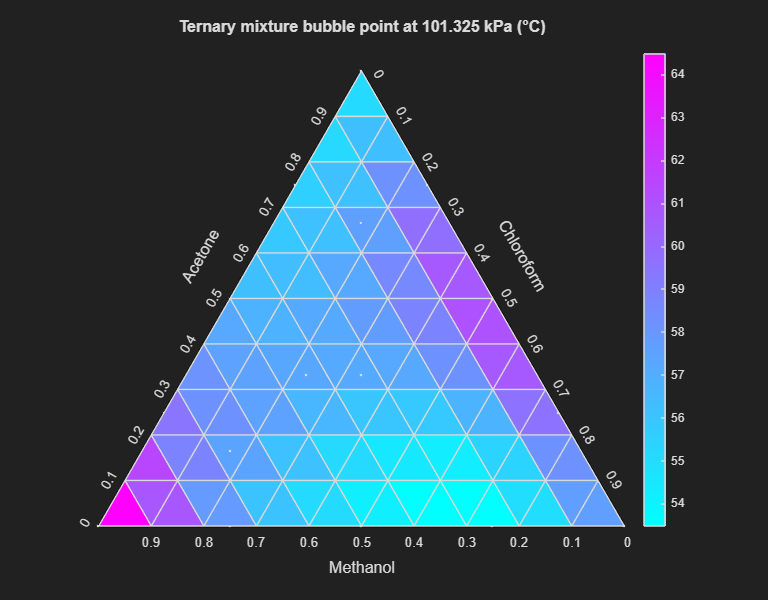

xlabel( TC, "Methanol", "FontSize", 12 )
ylabel( TC, "left", "Acetone", "FontSize", 12 )
ylabel( TC, "right", "Chloroform", "FontSize", 12 )
zlabel( TC, ...
    "Ternary mixture bubble point at 101.325 kPa (" + char( 176 ) + "C)", ...
    "FontSize", 12, "FontWeight", "bold" )
colormap( TC, cool() )
colorbar( TC )

## Customize the chart's appearance.

First, adjust the marker size of the discrete data points.

TC.MarkerSize = 20;

Modify the transparency of the surface.

TC.FaceAlpha = 0.75;

By default, when the `SurfaceType` is `"surface"`, the `EdgeColor` is `[0, 0, 0]`.

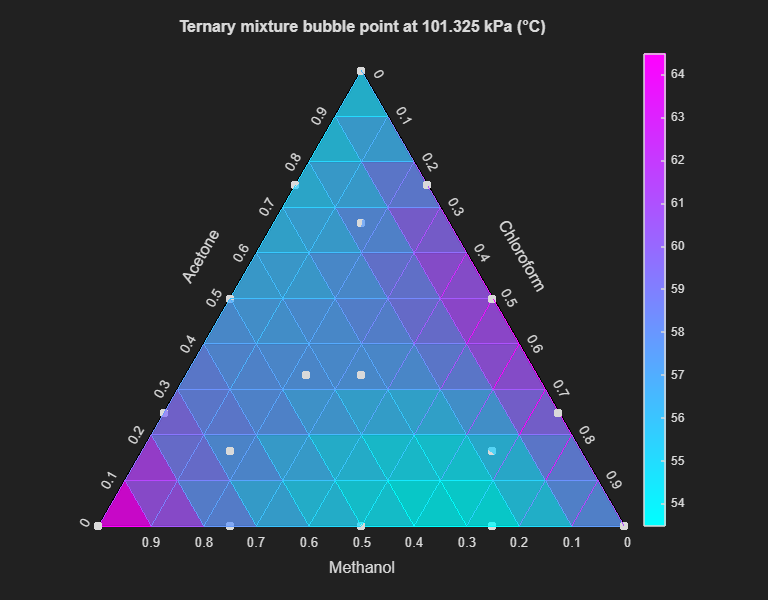

TC.EdgeColor = "flat";

## Modify the chart's surface type.

The ternary chart supports both the surface and mesh types.

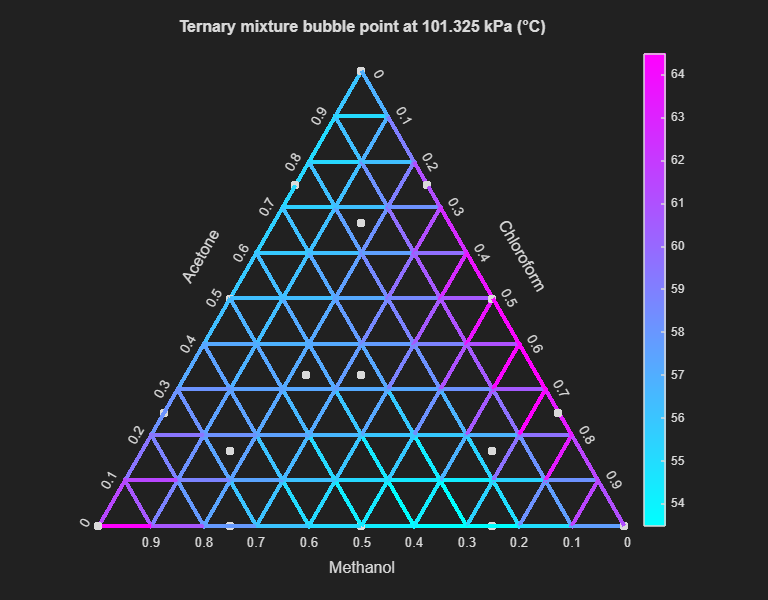

TC.SurfaceType = "mesh";
TC.LineWidth = 3;

## Modify the chart's grid and ticks.

We can set a new value for the `GridResolution` property.

TC.GridResolution = 20;

The `TickRate` property controls the number of axes ticks.

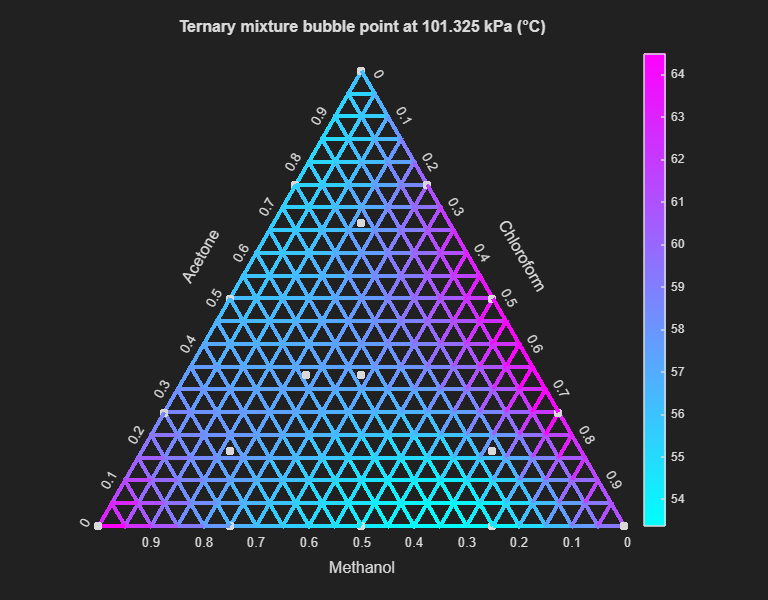

TC.TickRate = 2;

## Adjust the chart's view.

The ternary chart has the view method for adjusting the camera angle. This method has the same syntax as the usual axes [view](matlab: doc( "view" )) function.

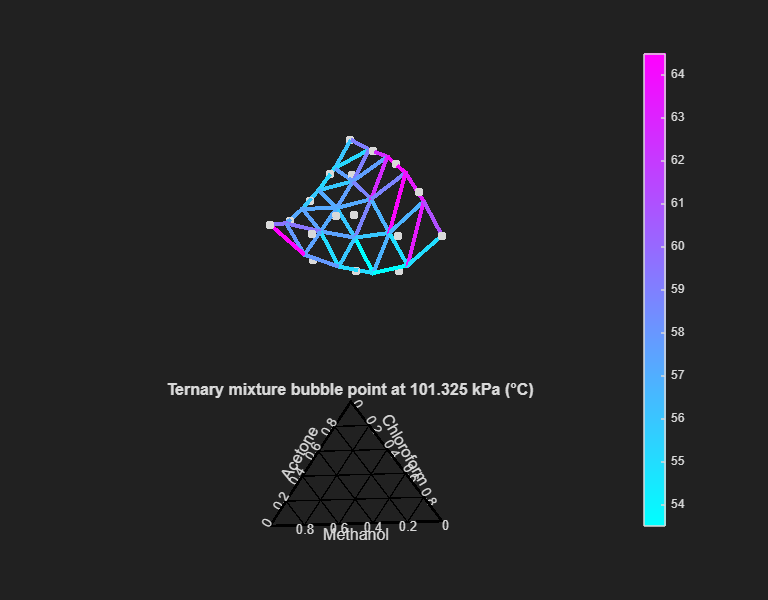

view( TC, [-2, 55] )
set( TC, "GridResolution", 5, "TickRate", 1 )

## Rotate the chart.

We can use the `rotate` method to rotate the chart clockwise or counter-clockwise by 120 degrees.

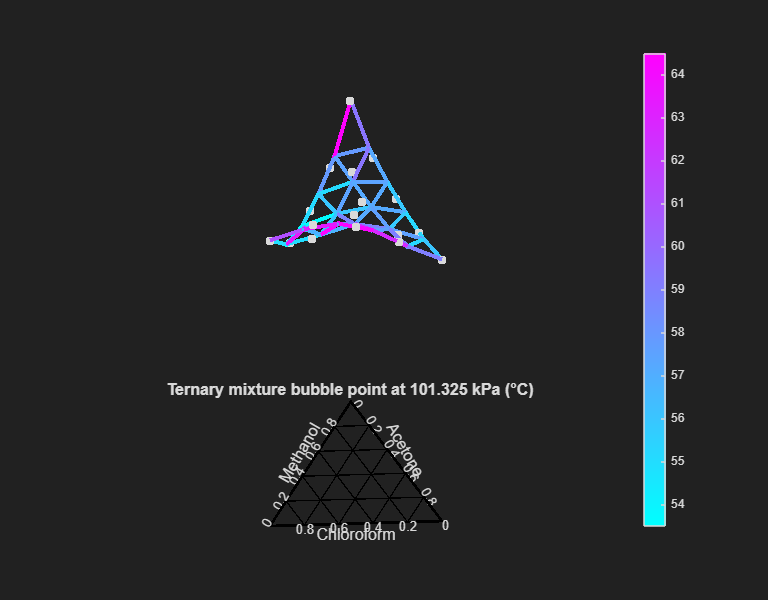

TC.rotate( "clockwise" )

## Enable the chart's control panel.

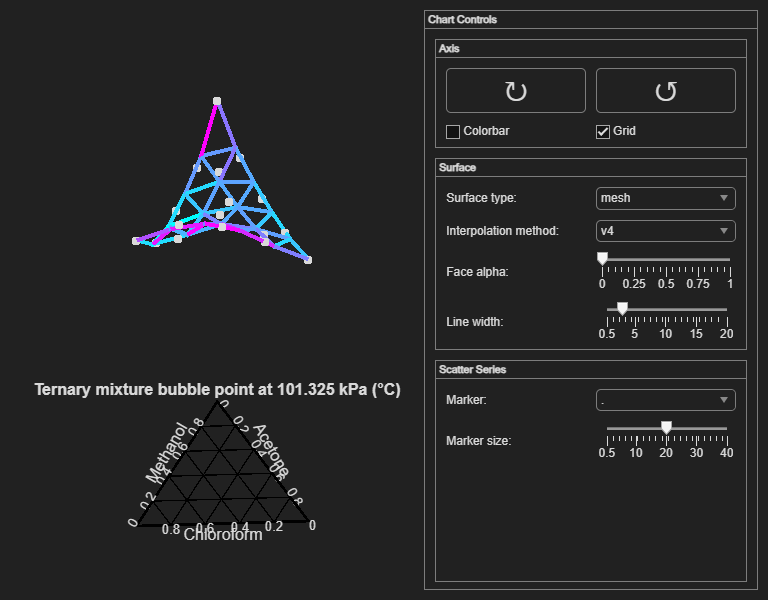

TC.Controls = "on";
colorbar( TC, "off" )

*Copyright 2018-2025 The MathWorks, Inc.*